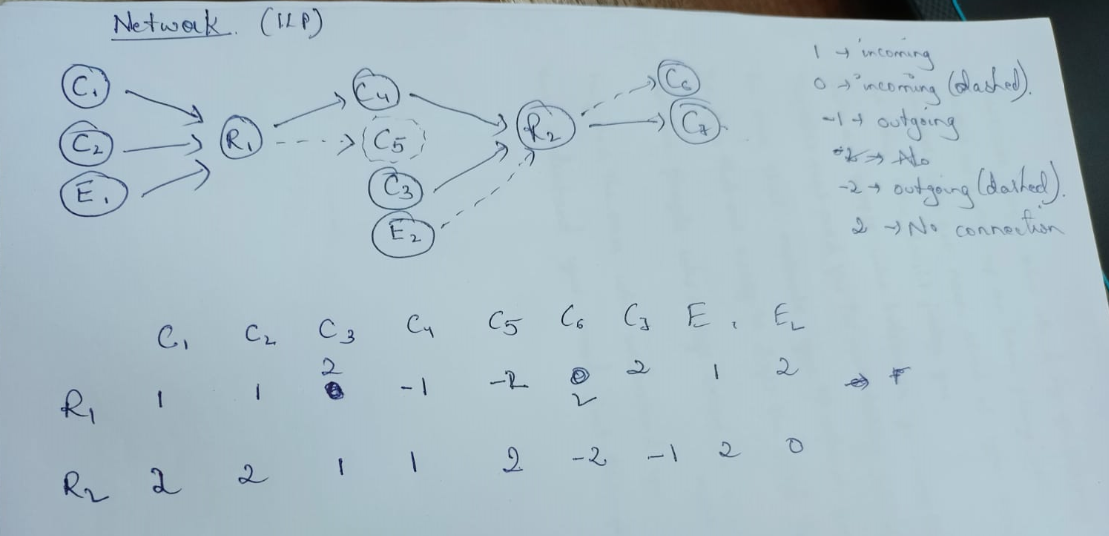

clc;
close all;
clear all;


max_metabolic = optimproblem('ObjectiveSense', 'max');
c = 7; % number of compound nodes
r = 2; % number of reaction nodes
e = 2; % number of enzyme nodes

% % Additional Constraints input
% compounds = [1,1,1]
% c_c = [1,2,3]
% enzymes = [1,1]
% e_e = [1,2]
% 
% c_ = reshape(repmat([1:c], r,1) ,[1,r*c]) 
% r_ = repmat([1:r], 1,c)
% r_r = reshape(repmat([1:r], e,1) ,[1,r*e])
% e_ = reshape(repmat([1:e], 1,r) ,[1,r*e])

% A =[1 -1 2 2 2 2 1 2 2 2 1;
%     2 1 1 -1 -1 2 -1 2 2 0 2;
%     2 2 2 2 2 1 -1 -1 -1 0 2];

A = [1 1 2 -1 -2 2 2 1 2;
    2 2 1 1 2 -2 -1 2 0];


[R,C] = find((A==1) + (A==0));

idx_c = C(C<=c);
idx_rx_c = R(C<=c);
idx_e = C(C>c)-c;
idx_rx_e = R(C>c);


C = optimvar('C',c,'Type','integer','LowerBound',0,'UpperBound',1);
R = optimvar('R',r,'Type','integer','LowerBound',0,'UpperBound',1);
E = optimvar('E',e,'Type','integer','LowerBound',0,'UpperBound',1);


max_metabolic.Constraints.C = R(idx_rx_c) <= C(idx_c);
max_metabolic.Constraints.E = R(idx_rx_e) <= E(idx_e);

cntrs=[];
for i =1:r
   cntrs = [cntrs ( R(i) + sum(  (1- C(idx_c(idx_rx_c==i)))   ) +  sum(   (1-E(idx_e(idx_rx_e==i)))  ))>=1];
end

max_metabolic.Constraints.R = cntrs;

% node values
C_node = [1,1,1,1,0,1,1];
E_node = [1 0];

% Additional constraints
max_metabolic.Constraints.A_c1 = C(find(C_node==1)) == 1;
max_metabolic.Constraints.A_c0 = C(find(C_node==0)) == 0;
max_metabolic.Constraints.A_e1 = E(find(E_node==1)) == 1;
max_metabolic.Constraints.A_e0 = E(find(E_node==0)) == 0;

show(max_metabolic)


  OptimizationProblem : 

	Solve for:
       C, E, R

	maximize :

	subject to C:
       R(1) - C(1) <= 0
       R(1) - C(2) <= 0
       R(2) - C(3) <= 0
       R(2) - C(4) <= 0

	subject to E:
       R(1) - E(1) <= 0
       R(2) - E(2) <= 0

	subject to R:
       -C(1) - C(2) - E(1) + R(1) >= -2
       -C(3) - C(4) - E(2) + R(2) >= -2

	subject to A_c1:
       C(1) == 1
       C(2) == 1
       C(3) == 1
       C(4) == 1
       C(6) == 1
       C(7) == 1

	subject to A_c0:
       C(5) == 0

	subject to A_e1:
       E(1) == 1

	subject to A_e0:
       E(2) == 0

	variable bounds:
       0 <= C(1) <= 1
       0 <= C(2) <= 1
       0 <= C(3) <= 1
       0 <= C(4) <= 1
       0 <= C(5) <= 1
       0 <= C(6) <= 1
       0 <= C(7) <= 1

       0 


sol = solve(max_metabolic);

Solving problem using intlinprog.
LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon variables are
integer within tolerance, options.IntegerTolerance = 1e-05 (the default value).




sol.E

ans =      1
     0


sol.R

ans =      1
     0


sol.C

ans =      1
     1
     1
     1
     0
     1
     1



A_c = A(:,1:9)

A_c =      1     1     2    -1    -2     2     2     1     2
     2     2     1     1     2    -2    -1     2     0


A_e = A(:,10:11)

Index in position 2 exceeds array bounds (must not exceed 9).


r1 = find(A_c(1,:)==1)
r1_ = [1 1]
r2 = find(A_c(2,:)==1)
r2_ = [2 2]
r3 = find(A_c(3,:)==1)
r3_ = [3]

e1 = find(A_e(1,:)<2)
e1_ = 1
e2 = find(A_e(2,:)<2) 
e2_ = 2
e3 = find(A_e(3,:)<2)
e3_ = 3

% node values
C_node = [1,1,1,0,0,1,1,0,0];
E_node = [0 1];





%max_metabolic.Constraints.C2 = R(1) <= C(2);
max_metabolic.Constraints.E1 = R(e1_) <= E(e1);
max_metabolic.Constraints.E2 = R(e2_) <= E(e2);
max_metabolic.Constraints.E3 = R(e3_) <= E(e3);



% max_metabolic.Constraints.R1 = R <= C
% Additional constraints
max_metabolic.Constraints.A_c1 = C(find(C_node==1)) == 1;
max_metabolic.Constraints.A_c0 = C(find(C_node==0)) == 0;
max_metabolic.Constraints.A_e1 = E(find(E_node==1)) == 1;
max_metabolic.Constraints.A_e0 = E(find(E_node==0)) == 0;

% max_metabolic.Constraints.A_e = E(e_e) == 1


% max_metabolic.Objective = (R(1) +  (1-C(1)) + (1-C(2)) + (1-E(1))) - 1
max_metabolic.Objective = ones(1,r)*R - (ones(1,c)*C +ones(1,e)*E) + (length(C) + length(E)) - 1;


Our final Optimization problem now becomes...

show(max_metabolic)

sol = solve(max_metabolic);

sol.E
sol.R
sol.C

### Convention

Incoming edges = 1

Incoming edges (dashed) = 0

Outgoing edges = -1

No connection = 2

    C1 - C9 E1 E2

R1

R2

R3